AChmut_datapath=["/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220206_112_8_AChMut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001",
                 "/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001"
                 ]

AChmut_datapath = 5×1 string array
    "/Volumes/PcSSDA/AChMut/20220422_112_AChmtut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220206_112_8_AChMut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220425_109_AChmut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220207_109_AChMut_SW_001"
    "/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001"



ExperimentNames=["20220422_112_AChmtut_SW_001",
                 "20220206_112_8_AChMut_SW_001",
                 "20220425_109_AChmut_SW_001",
                 "20220207_109_AChMut_SW_001",
                 "20220712_PM29_111_Achmut_001"
                 ]

ExperimentNames = 5×1 string array
    "20220422_112_AChmtut_SW_001"
    "20220206_112_8_AChMut_SW_001"
    "20220425_109_AChmut_SW_001"
    "20220207_109_AChMut_SW_001"
    "20220712_PM29_111_Achmut_001"


Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

states_pooled_all = [];
tau_pooled_all = [];
states_index = [];
states_addition = zeros(12*900, 1)+1;
states_added_index = zeros(12*900, 1);
tau_addition = nan(12*900 ,1);

for i=1:5
    
    rawData=([Temperature_path,convertStringsToChars(ExperimentNames(i)),'.mat'])
    OptResults=([Temperature_path,convertStringsToChars(ExperimentNames(i)),'OptResults.mat'])

    cd(convertStringsToChars(AChmut_datapath(i)))
    load(rawData)
    tau_pooled_all = [tau_pooled_all; tau_addition; tau_empTrunc_pooled];
    states_pooled_all = [states_pooled_all; states_addition; states_pooled];
    states_index = [states_index; states_added_index; (zeros(length(states_pooled),1)+1)];
    eval(['time_pooled',num2str(i),'=time_pooled;'])
    eval(['tau_empTrunc_pooled',num2str(i),'=tau_empTrunc_pooled;'])
    eval(['states_pooled',num2str(i),'=states_pooled;'])
end

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001.mat'

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults.mat'

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220206_112_8_AChMut_SW_001.mat'

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220206_112_8_AChMut_SW_001OptResults.mat'

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220425_109_AChmut_SW_001.mat'

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220425_109_AChmut_SW_001OptResults.mat'

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220207_109_AChMut_SW_001.mat'

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220207_109_AChMut_SW_001OptResults.mat'

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220712_PM29_111_Achmut_001.mat'

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220712_PM29_111_Achmut_001OptResults.mat'


cd(Temperature_path)

size(tau_pooled_all)

ans =       104159           1


size(states_pooled_all)

ans =       104159           1


size(states_index)

ans =       104159           1


rawData_all=([Temperature_path, 'data_all.mat'])

rawData_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/data_all.mat'

optResults_all = ([Temperature_path, 'results_all.mat'])

optResults_all = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/results_all.mat'

save(rawData_all, 'tau_pooled_all', 'states_pooled_all', 'states_index')

example2_Optimization(rawData_all, OptResults_all)

load(optResults_all)
load(rawData_all)

flagsWakeREM = states_pooled_all;

initial_temperature = -1; % negative value produces an estimated initial temperature
SF=4;

% Use the median parameter values from Table 1:
p.sizePWP = 2.25;              % window size (in hours) of the prior wake prevelance (PWP)
p.shiftPWP = 5;          % window shift (in hours) of the prior wake prevelance (PWP)
p.lowerAsymptote = 4.18;   % Lower asymptote value (in C)
p.upperAsymptote =  4.1441;  % Upper Asymptote value (in C)
p.wakeTimeConstant = 0.1957;  % Time constant of wake and REM states
p.nremTimeConstant = 0.0343;  % Time constant of NREM sleep
p.scalePWP = 0.0043;          % The multiplier of PWP values
p.circadianAmplitude = 0.000211325926138286;% The multiplier of the circadian values
p.circadianPhase = 0.1086;   % Phase shift of circadian process (in hours)

[simulatedT,asymptots] = simulateBrainTemperature (...
        flagsWakeREM, initial_temperature, SF, p.sizePWP, p.shiftPWP,...
        [p.lowerAsymptote, p.upperAsymptote, p.wakeTimeConstant, ...
         p.nremTimeConstant, p.scalePWP, p.circadianAmplitude, p.circadianPhase...
        ]);

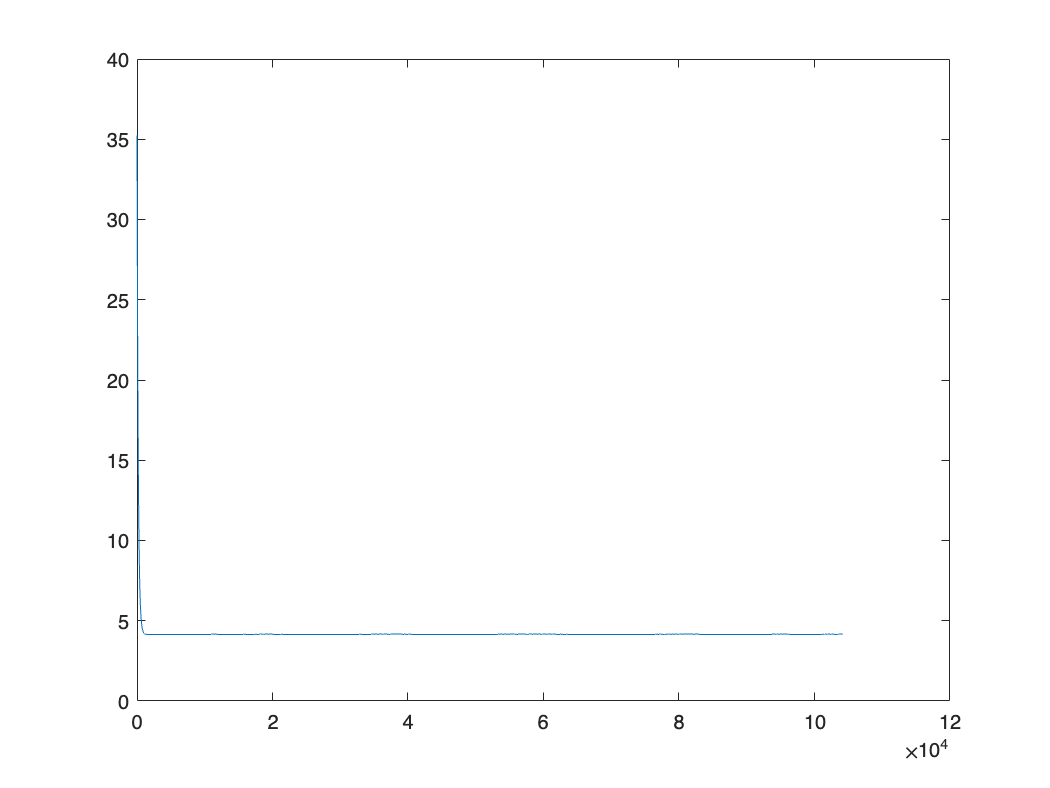

figure
plot(simulatedT)